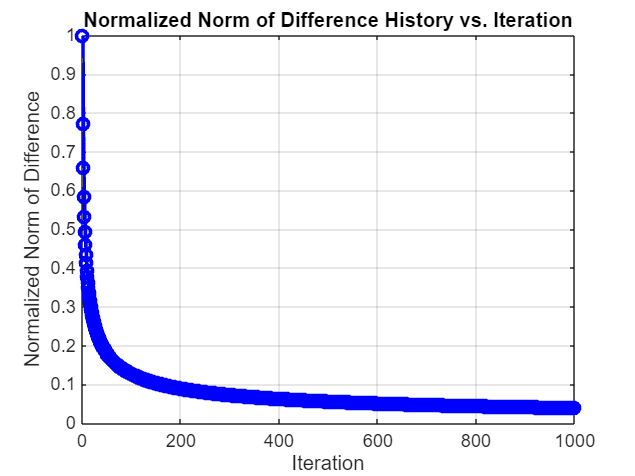

clear; clc; close all;
%Set up initial Conditions
M=.5;
T_inf = 300;
P_inf = 10^5;
T_static = 285.6;
P_static = 83700; %Pascal
V_inf = 173.55;
gamma = 1.4; R =287;
rho_inf = P_inf/(R*T_inf);
B=1-M^2;
%Set up your grid
dx=.1;dy=.1;
nx=411;ny=201; offset = -20.5;
[y_grid, x_grid] = meshgrid(0:dy:(ny-1)*dy, offset:dx:(nx-1)*dx+offset); %[y_grid, x_grid] = meshgrid(0:dy:(ny-1)*dy, 0:dx:(nx-1)*dx);
%x_grid=y_grid;
term1 = 1/(2*B/dx^2+2/dy^2);
dydx = (69.722 - x_grid.^2 + x_grid - 0.25).^-0.5 .* (-x_grid + 0.5);
%Calculate initiaization
phi_old = V_inf*x_grid;
% Logical truth table
Truth_Table = (x_grid(:, 1) > -.5 & x_grid(:, 1) < .5) | (x_grid(:, 1) == .5) | (x_grid(:, 1) == -.5);
% If you need indices where the conditions are true
phi_old(:,1) = phi_old(:,2)-(dy*V_inf*dydx(:,1).*Truth_Table(:,1)); %write airfoil boundary condition
phi_new = phi_old; %create new based off of old

%set up boundary conditions
Iteration_num = 1000;
residual = zeros(1,Iteration_num);
for k = 1:Iteration_num
    for i=2:nx-1
        for j = 2:ny-1
            %fprintf("i:%.f",i);fprintf("j:%.f \n",j)
            phi_new(i,j) = term1*(phi_new(i,j-1)/dy^2 + B*phi_new(i-1,j)/dx^2 + phi_old(i,j+1)/dy^2 + B*phi_old(i+1,j)/dx^2);
        end
    end
    %apply numen boundary conditions again
    phi_new(:,1) = phi_new(:,2)-(dy*V_inf.*dydx(:,1).*Truth_Table(:,1));
    del_e = norm(phi_new-phi_old);
    if k == 1
        del_0 = del_e;
    end
    residual(k) =  del_e/del_0;
    phi_old = phi_new;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%PostProcessing Stuff
%calculate u and v's needed for Post Processing
u = zeros(nx, ny);
v = zeros(nx, ny);

% Calculate u
for i = 2:nx-1
    for j = 1:ny
        u(i, j) = (phi_new(i+1, j) - phi_new(i-1, j)) / (2 * dx);
    end
end

% Calculate v
for i = 1:nx
    for j = 2:ny-1
        v(i, j) = (phi_new(i, j+1) - phi_new(i, j-1)) / (2 * dy);
    end
end

%solve for the boundary that isnt covered in the for loops above
u(1, :) = (phi_new(2, :) - phi_new(1, :)) / dx;
u(end, :) = (phi_new(end, :) - phi_new(end-1, :)) / dx;
v(:, 1) = (phi_new(:, 2) - phi_new(:, 1)) / dy;
v(:, end) = (phi_new(:, end) - phi_new(:, end-1)) / dy;

%calculate your Cp
Cpu = u(:,1).*Truth_Table(:,1);
Cpv = v(:,1).*Truth_Table(:,1);
p=P_inf*(1-(gamma-1)/2*M^2*((u(:,1).^2+v(:,1).^2)/V_inf^2-1)).^(gamma/(gamma-1));
Cp = (p-P_inf)./(.5*gamma*P_inf*M^2).*Truth_Table(:,1);
if 1==1
    %plot your error:
    % Plotting the residuals vs iteration
    figure;
    plot(1:length(residual), residual, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b');
    % Adding labels and title
    xlabel('Iteration');
    ylabel('Normalized Norm of Difference');
    title('Normalized Norm of Difference History vs. Iteration');
    % Display grid
    grid on;
end

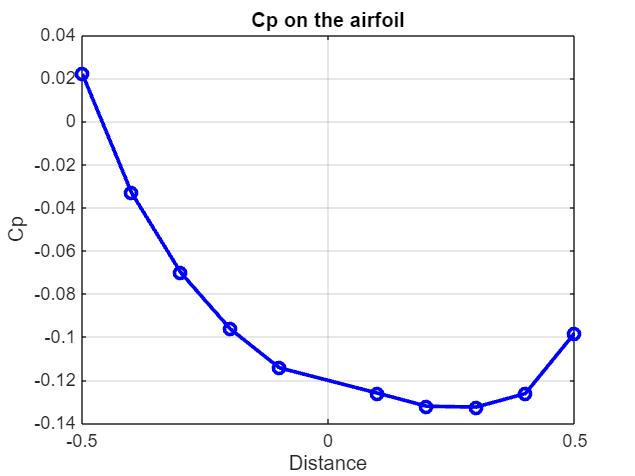

%Plot your Cp
Cp_xgrid = x_grid(:,1).*Truth_Table(:,1); %set all Cp's not on the airfoil to zero
Cp_xgrid = Cp_xgrid(Cp_xgrid ~= 0); %remove all zeros from your x points
Cp_xgrid = [0;Cp_xgrid]; %you must add back the zero position it removes
Cp = Cp(Cp ~= 0); %remove all zero Cp points
if 1==1
    %plot your Cp:
    figure;
    plot(Cp_xgrid(2:end), Cp(2:end), '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b');
    % Adding labels and title
    xlabel('Distance');
    ylabel('Cp');
    title('Cp on the airfoil');
    % Display grid
    grid on;
end

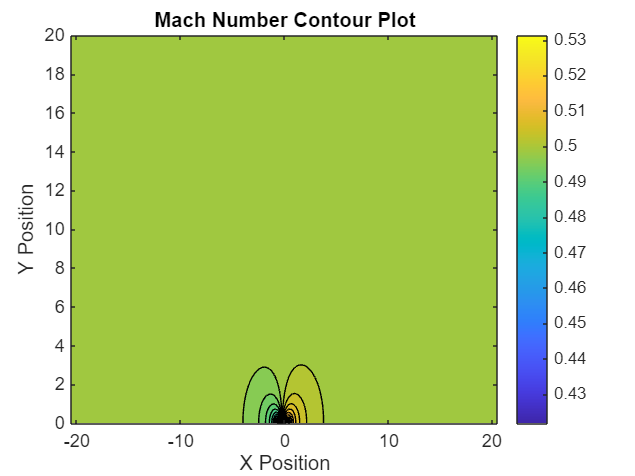

%calculate for Mach:
V = sqrt(u.^2+v.^2);
To = T_inf*(1+(gamma-1)/2*M^2);
Cp_air = 1000;
T = To - V.^2/(2*Cp_air);
a=sqrt(gamma*R.*T);
M_list = V./a;
%Plot countour plots
if 1==1
    % Create a contour plot
    figure;
    contourf(x_grid, y_grid, M_list, 40); % 40 contours, adjust as needed
    colorbar; % Show a color bar to indicate Mach number scale
    xlabel('X Position');
    ylabel('Y Position');
    title('Mach Number Contour Plot');
end